## Fit bioluminescence and virus titers data with SCG model

Load experimental data

clear;clc;
biolu_data_ko = importdata('biolu_data_ko.txt');

Optimize using fminsearch

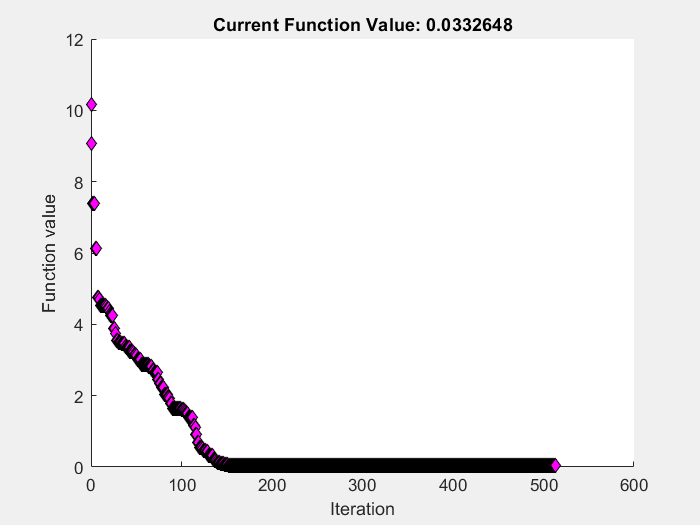

par_base = importdata('par_scg.txt');
par_base = par_base.data;

FitFcn = @(par_fit)Fit_err(biolu_data_ko, par_fit);

options_fmin = optimset('PlotFcns',@optimplotfval);
[p, fminres] = fminsearch(FitFcn, par_base, options_fmin);

disp(p');

   1.0e+04 *

    0.0000    0.0000    0.0000    3.3594    0.0000

